# Робот-манипулятор двухзвенный 

Выполнил: студент группы R4136c, Ларченков Артем

Цель работы: Оптимизация траектории робота с помощью метода роя.


$$reward = -\frac{ t^2}{1+|x| + |y| + |z|}$$


## Open the model with previous (initial) data

Open the open-chain model with settings for jumping behaviour

% res_1_1 = 'optData_step_1_jump_15May23_2234.mat';
% % res_1_2 = 'optData_Ga15May23_2321.mat';
% % res_1_1 = 'optData_step_1_jump_1.mat';
% 
% load(res_1_2)
% parameterss % model parameters
% mdlName = 'robott_old'; % main model
% open_system(mdlName); % open main model
% % jump = 1; run = 0; % option for jumping 
% sim_oc_jump = sim(mdlName,'StopTime','10','SrcWorkspace','current');
% measBody = get(sim_oc_jump.yout,'measBody').Values;
% 
% figure
% plot(measBody.X.Time, measBody.X.Data, ...
%      measBody.Y.Time, measBody.Y.Data, ...
%      measBody.Z.Time, measBody.Z.Data, ...
%     'linewidth', 1)
% grid on
% xlabel('$t$, [c]','Interpreter','latex')
% ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
% legend('y','z','x')

## Set optimization

Define the number of end-effector's trajectory points and initial parameters 

numPoints = 2;     
alpha = 0.08; % [rad]
gait_period = 0.40;

Create initial conditions to seed the initial population for optimization.Initial conditions consist 4 points: (2 trajectory points, alpha value, gait period value)

p0 = [zeros(1,numPoints) alpha gait_period]

p0 =          0         0    0.0800    0.4000


## Set optimization options

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

opts = optimoptions('particleswarm');
opts.Display = 'iter';
opts.MaxIterations = 10;

opts.InitialSwarmMatrix = repmat(p0,[numPoints 1]); % Add copies of initial gait 
opts.PlotFcn = @pswplotbestf; % Add progress plot of fitness function
opts.UseParallel = false;

## Set constraints for trajectory points, alpha and gait period

upperBnd = [ 0.185*ones(1,numPoints), ...    % r max
             10*pi/4,...                      % alpha max
             0.50];                           % gait_period max
lowerBnd = [ 0.004*ones(1,numPoints), ...     % r min
             5*pi/4,...                      % alpha min
             0.40];                          % gait_period min

## Run optimization

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html) function from Global Optimization Toolbox to optimize the walking gait, with **simulateOpenChainRobot** as the fitness function.

Some initial particle positions are not between bounds lb and ub; PARTICLESWARM
shifted them to satisfy the bounds.    0.0040    0.0040    3.9270    0.4000

    0.0040    0.0040    3.9270    0.4000

    0.1332    0.0857    5.2936    0.4476

    0.1159    0.0476    4.4047    0.4362

    0.0661    0.1334    7.3991    0.4788

    0.1734    0.1590    4.2972    0.4780

    0.0266    0.0550    7.5793    0.4669

    0.1362    0.1363    5.4939    0.4134

    0.1210    0.0289    4.1131    0.4022

    0.1548    0.1554    5.2715    0.4560

    0.0761    0.0291    6.8171    0.4301

    0.1397    0.1105    7.0477    0.4939

    0.1552    0.0703    6.0668    0.4981

    0.0624    0.1500    6.6218    0.4287

    0.1040    0.0952    7.4363    0.4801

    0.1812    0.0926    4.1422    0.4896

    0.1034    0.1627    5.1195    0.4598

    0.0638    0.0679    4.1084    0.4884

    0.1161    0.0853    4.6946    0.4944

    0.0693    0.1784    6.7551    0.4549

    0.1409    0.0117    6.7613    0.4728

   

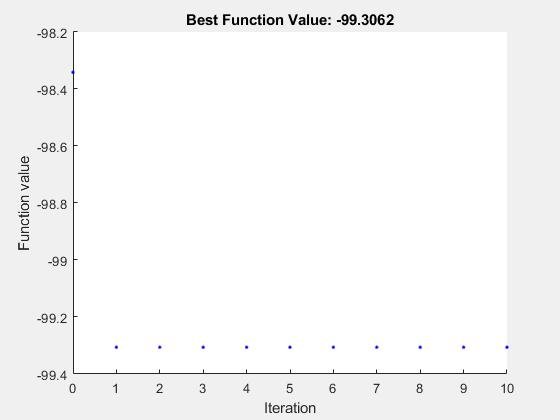

parameters % model parameters
mdlName = 'robott_20201_fin'; % main model

costFcn = @(p)optOpenChainmove(p,mdlName);

[pFinal,reward] = particleswarm(costFcn,numPoints+2,lowerBnd,upperBnd,opts);

disp(['Final reward function value: ' num2str(-reward)])

Final reward function value: 99.3062


## Analyze and save results

r_motion = [pFinal(1:numPoints) pFinal(1)];
alpha   = pFinal(numPoints+1)

alpha = 7.8540

gait_period = pFinal(numPoints+1+1)

gait_period = 0.5000

traj_times  = linspace(0,gait_period,numPoints+1);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
spln = createSpline(r_motion,gait_period,evalTimes);
r_der = createSmoothTrajectory(r_motion, gait_period);

Plot the resulting trajectory

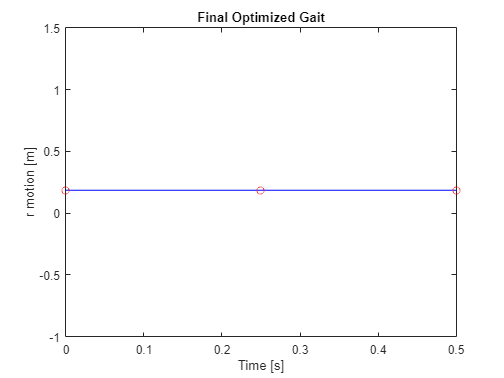

figure
plot(evalTimes,spln(1,:),'b-',traj_times,r_motion,'ro');
title('Final Optimized Gait');
xlabel('Time [s]');
ylabel('r motion [m]');

Save results to a timestamped MAT-file

outFileName = ['optData_Roy' datestr(now,'ddmmmyy_HHMM')];
save(outFileName,'reward','gait_period','traj_times','r_motion','alpha','r_der');

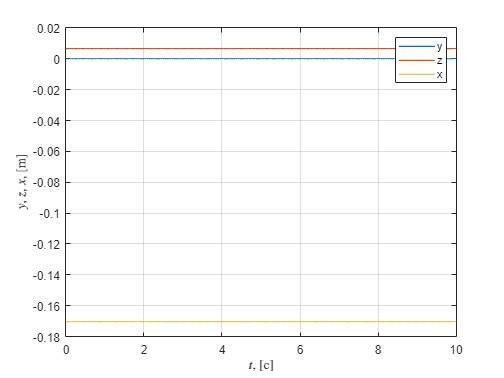

sim_traj = sim(mdlName,'StopTime','10','SrcWorkspace','current');
measBody = get(sim_traj.yout,'measBody').Values;

figure
plot(measBody.Y.Time, measBody.Y.Data, ...
     measBody.Z.Time, measBody.Z.Data, ...
     measBody.X.Time, measBody.X.Data, ...
    'linewidth', 1)
grid on
xlabel('$t$, [c]','Interpreter','latex')
ylabel('$y$, $z$, $x$, [m]','Interpreter','latex')
legend('y','z','x')